% Read image
clc
clear

N = 16;
image_vector = zeros(40000,N);

for i = 1:N
    if (i < 10)
        number = '0' + string(i);
    else
        number = string(i);
    end
    
    name = './DB1/db1_' + number + '.jpg';
    
    RGB = imread(name);
    
    croppedImage = faceDetection(RGB);
    if(i == 1)
        imshow(croppedImage)
    end
    
    
    grayImage = im2gray(im2double(croppedImage));
    
    image_vector(:,i) = grayImage(:);
     
end

% Mean-face
meanFace = sum(image_vector,2)/N;
meanFaceImage = reshape(meanFace, 200, 200);
imshow(meanFaceImage);

% Subtract mean
A = im2double(image_vector)-meanFace;

% Covariance 
% C = AA';
C1 = A'*A;

[V, D] = eig(C1);

u = A*V;

% Normalization
for i=1:16
    u(:,i) = u(:,i)/norm(u(:,i));
end

% Weights
w = u'*A;

% Test
% I = meanFace + ( A * w(:,7) );
% imshow(reshape(I,[200 200]));


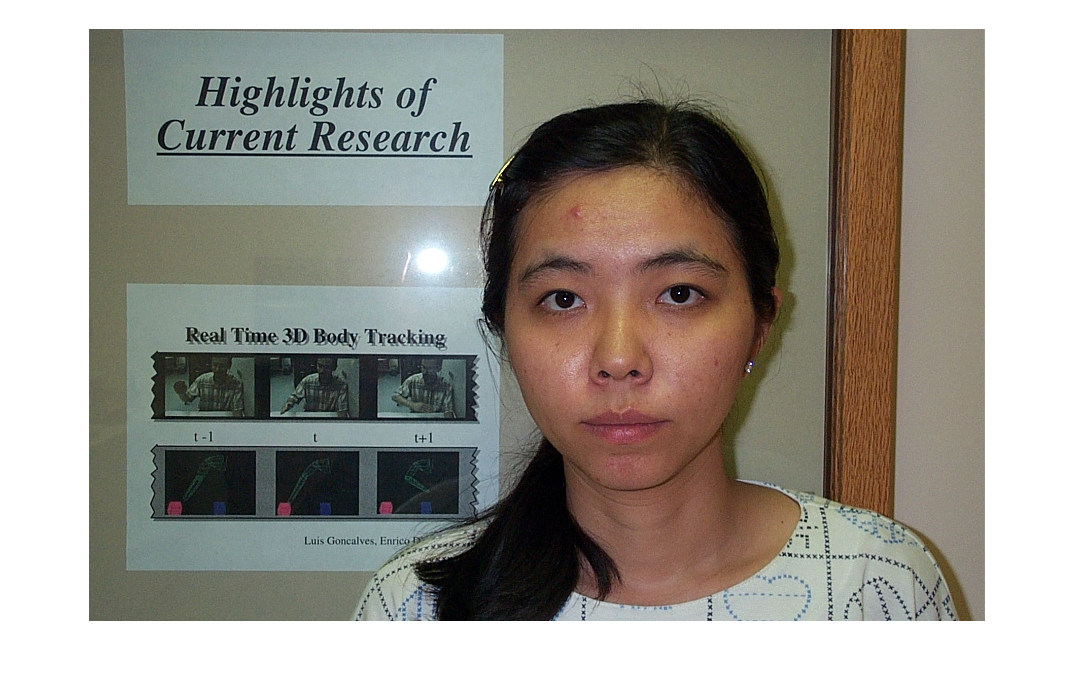

% Recognition
RGB = imread('./DB2/il_16.jpg');

croppedImage = faceDetection(RGB);
grayImage = im2gray(im2double(croppedImage));
grayImage = grayImage(:);

theta = grayImage - meanFace;

qw = u'*theta;

e = zeros(16,16);

for i = 1:16
    e(:,i) = w(:,i) - qw(:);
end

e2 = sum(abs(e));

[value, index] = min(abs(e2));

if (index < 10)
    number = '0' + string(index);
else
    number = string(index);
end

name = './DB1/db1_' + number + '.jpg';

imshow(RGB);

Possible match!


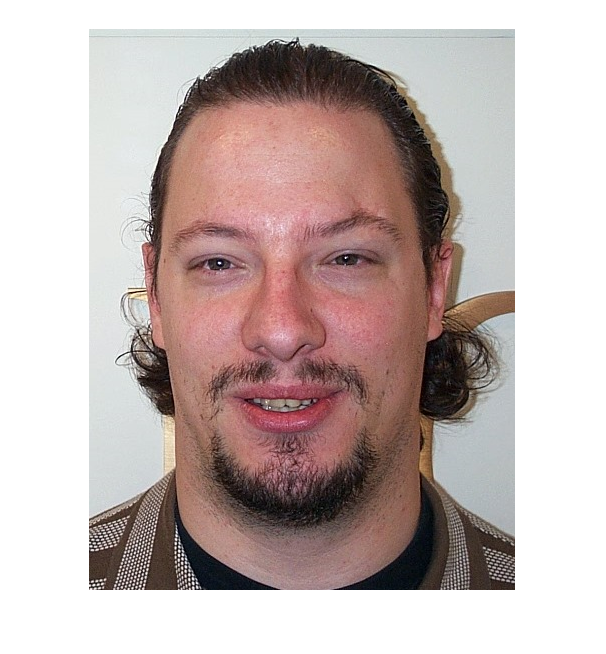

if(value < 200)
    disp('Possible match!')
    imshow(imread(name));
end

function croppedImage = faceDetection(RGB)
    % White balance
    rgbImageWhite = cWhitePatch(RGB);
%     disp('Face mask'), imshow(rgbImageWhite)
     
    % Face mask
    mask = faceMask(rgbImageWhite);
%     disp('Face mask'), imshow(mask)
    
    % Eye map
    map = eyeMap(rgbImageWhite);
%     disp('Eye map'), imshow(map)
    
    % Combine
    res = map & mask;
%     disp('Eye map + face mask'), imshow(res)
    
    % Cleaning
    res = cleaning(res);
    
    % Get eye coordinates
    [lab,~]=bwlabel(res);
    stats = regionprops(lab);
    eye1 = getfield(stats,{1},'Centroid');
    y1 = eye1(1);
    x1 = eye1(2);
    eye2 = getfield(stats,{2},'Centroid');
    y2 = eye2(1);
    x2 = eye2(2);
    
    % Rotate the images based on the eyes
    rotatedImage = rotate_image(RGB,y1,x1,y2,x2);
    % disp('Rotated image'), imshow(rotatedImage);
    
    % Get new eye coordinates
    map = rotate_image(res,y1,x1,y2,x2);
    [lab,~]=bwlabel(map);
    stats2 = regionprops(lab);
    eye1 = getfield(stats2,{1},'Centroid');
    eye2 = getfield(stats2,{2},'Centroid');
    x1 = eye1(1);
    y1 = eye1(2);
    x2 = eye2(1);
    y2 = eye2(2);
    
    % Crop the image square for eigenfaces
    croppedImage = crop(rotatedImage, x1, y1, x2, y2);
end